# M E 325 Exam 1 Problem 2

### Group 6

#### Parker Wilson, Preston Witte, Mike Lawlor, Justin Merkel

For a material with the following properties, plot the elastic and plastic strainamplitudes, ∆εf, verses number of stress reversals, 2Nf using logarithmic axes.The Manson-Coffin equation, relating strain amplitude to number of stress re-versals is:

∆εf/2 = σ`′`f/E (2Nf)^b + ε′f(2Nf)^c

Where:

`•`ε′f is the fatigue ductility coefficient and has a value of 0.59

`•`σ′f is the fatigue strength coefficient and has a value of 277.5 kpsi

`•`b is the slope of the elastic line and has a value of -0.087

`•`c is the slope of the plastic line and has a value of -0.58

`•`E is Young’s Modulus of Elasticity and has a value of 30 ×106 psi

Determine:

1. the transition life in reversals

2. the strain amplitude, ∆ε/2 at 50 000 reversals

Plot the strain amplitude on log-log axes

Submit:

`•`Results generated by the software of your team’s choice.

`•`Along with numerical results, include the symbolic equations used to gen-erate them

`•`The plot of strain amplitude vs number of reversals. Clearly delineate the

plastic and elastic lines

Clearing command window and workspace

clc
clear all

Creating vaolues for sigma and epsillon

eprime=0.59;
sigmaprime=277500;

Constants for Manson Coffin Equation

b=-0.087;
c=-0.58;

Young's Modulus

E=30*10^6;

Creating equations to be plotted where N is the number of reversals

N=logspace(1,6);

Strain Equations

ElasticStrain=(sigmaprime/E)*(2*N).^b;
PlasticStrain=eprime*(2*N).^c;

TotalStrain=PlasticStrain+ElasticStrain;

idx = find(abs(ElasticStrain-PlasticStrain)==min(abs(ElasticStrain-PlasticStrain)));
Transition_Life= N(idx);
yvalue=ElasticStrain(idx);

Generating a Log-Log graph, with all three strain equations plotted.

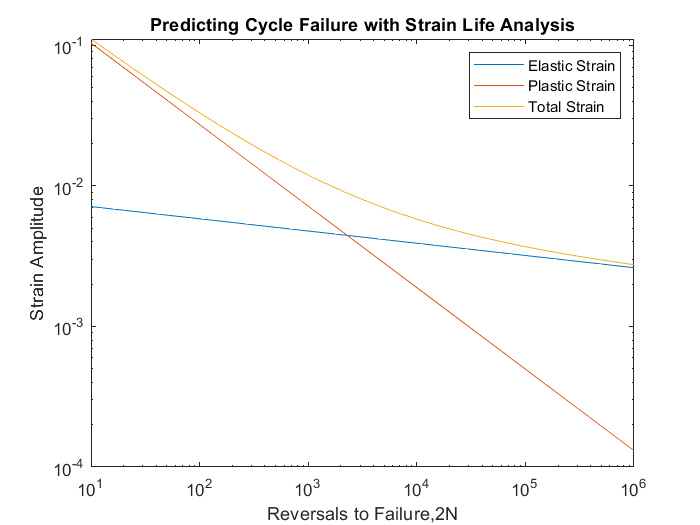

loglog(N,ElasticStrain,N,PlasticStrain,N,TotalStrain)
legend({'Elastic Strain','Plastic Strain','Total Strain'},'Location','northeast','Orientation','vertical')
title('Predicting Cycle Failure with Strain Life Analysis')
xlabel('Reversals to Failure,2N')
ylabel('Strain Amplitude')

Calculating the Strain amplitude at 50000 Cycles and displaying results.

N=50000;
StrainAmplitude_50000=eprime*(2*N).^c+(sigmaprime/E)*(2*N).^b;

X = sprintf('Strain Amplitude = %s',StrainAmplitude_50000);
disp(X);

Strain Amplitude = 4.140127e-03


Y= sprintf('Transition Life = %s Reversals to Failure',Transition_Life);
disp(Y)

Transition Life = 2.222996e+03 Reversals to Failure
